clear; close all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 0 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms M m l g u z z_dot theta theta_dot t q1 q2

% define the system state
x = [z; z_dot; theta; theta_dot];

% define system dynamics
y_ddot=(-m*l*sin(theta)*theta_dot^2 + m*g*sin(theta)*cos(theta) + u)/...
    (M + m*sin(theta)^2);
theta_ddot=(-m*l*sin(theta)*cos(theta)*theta_dot^2 + (M+m)*g*sin(theta) +...
    u*cos(theta))/...
    (l*(M+m*sin(theta)^2));

xdot = [z_dot; y_ddot; theta_dot;theta_ddot]

$$xdot = \left(\begin{array}{c} \dot{z}\\ \frac{-l\,m\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{m\,{\sin\left(\theta \right)}^{2}+M}\\ \dot{\theta }\\ \frac{-l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\,\left(M+m\right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)} \end{array}\right)$$



% define the set of parameters specific to our ODE
base_params.M = 1.0731;
base_params.m = 0.2300;
base_params.l= 0.3302;
base_params.g = 9.8;

%linearization starts here

% equilibrium point
x_bar = [0; 0; 0; 0];
u_bar = 0;

% find jacobian for any point x
A_raw = jacobian(xdot,x);
B_raw = jacobian(xdot,u);

% substitute parameters as defined above
A_specific = subs(subs(subs(subs(A_raw,m,base_params.m),M,base_params.M), l, base_params.l), g, base_params.g);
B_specific = subs(subs(subs(subs(B_raw,m,base_params.m),M,base_params.M), l, base_params.l), g, base_params.g);

% find jacobian around the equilibrium point
A = subs(subs(A_specific,x,x_bar), u, u_bar)

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{460}{219} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{13031000}{361569} & 0 \end{array}\right)$$

B = subs(subs(B_specific,x,x_bar), u, u_bar)

$$B = \left(\begin{array}{c} 0\\ \frac{10000}{10731}\\ 0\\ \frac{50000000}{17716881} \end{array}\right)$$

C = [1, 0, 0, 0;
    0, 0, 1, 0]         % can only observe z and theta, not their velocities

C =      1     0     0     0
     0     0     1     0


Qo = obsv(A,C)

Qo =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0         0    2.1005         0
         0         0   36.0401         0
         0         0         0    2.1005
         0         0         0   36.0401


rank_Qo = rank(Qo)

rank_Qo = 4


observable = rank_Qo == size(x, 1)          % returns 1 if the system is observable

observable = logical
   1



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_double = double(A);
B_double = double(B);
C_double = C;

% desiging observer matrix L
poles_L_1 = [-10, -11, -12, -13];
poles_L_2 = [-40, -41, -42, -43];

negK_L_1 = place(A_double', C_double',poles_L_1);
negK_L_2 = place(A_double', C_double',poles_L_2);
K_L_1 = -negK_L_1;               % to convert to the convention used in class
K_L_2 = -negK_L_2;               % to convert to the convention used in class

L_1 = K_L_1'

L_1 =   -22.9338   -1.0388
 -130.7798  -14.0775
   -0.9570  -23.0662
  -10.9830 -168.2589


L_2 = K_L_2'

L_2 = 	1.0e+03 *

   -0.0829   -0.0011
   -1.7161   -0.0464
   -0.0009   -0.0831
   -0.0380   -1.7629



% verifies that our observer matrices place poles at correct locations
sort(eig(A_double + L_1 * C_double), 'descend') 

ans =   -10.0000
  -11.0000
  -12.0000
  -13.0000


sort(eig(A_double + L_2 * C_double), 'descend') 

ans =   -40.0000
  -41.0000
  -42.0000
  -43.0000




% desigining controller matrix K
poles_K = [-5.1, -5.2, -5.3, -5.4];
negK = place(A_double, B_double, poles_K);
K = -negK;

% verifies pole placement of controller matrix K
sort(eig(A_double + B_double*K), 'descend') 

ans =    -5.1000
   -5.2000
   -5.3000
   -5.4000


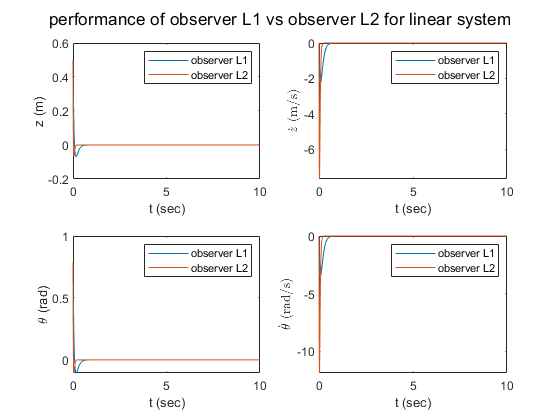




% preparing for simulations
x0 = [-0.5; 0; -pi/4; 0];
xhat0 = [0; 0; 0; 0];
x0_gen = [x0; xhat0];    % concatenate initial conditions to simulate simultaneously

options = odeset('RelTol',1e-7,'AbsTol',1e-7); 
Tspan = linspace(0,10,1e3);                      %choose time span from 0 to 1 because error dies out quickly


linearized_params.A = A_double;
linearized_params.B = B_double;
linearized_params.C= C_double;
linearized_params.K = K;


% define parameters for L1 and simulate for linear system
linearized_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_linear,Tspan,x0_gen,options, linearized_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for linear system
linearized_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_linear,Tspan,x0_gen,options, linearized_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);


% plotting a figure with 4 subplots for linear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1(:,1))
hold on                     
plot(t_L2, z_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")

subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1(:,1))
hold on                     
plot(t_L2, zdot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1(:,1))
hold on                     
plot(t_L2, theta_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1(:,1))
hold on                     
plot(t_L2, thetadot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')

sgtitle('performance of observer L1 vs observer L2 for linear system')




% prepare base paramaeters for nonlinear system
nonlinear_params = base_params;
nonlinear_params.A = A_double;
nonlinear_params.B = B_double;
nonlinear_params.C= C_double;
nonlinear_params.K = K;


% define parameters for L1 and simulate for nonlinear system
nonlinear_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for nonlinear system
nonlinear_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_nl,Tspan,x0_gen,options, nonlinear_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);

% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1(:,1))
hold on                     
plot(t_L2, z_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")

subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1(:,1))
hold on                     
plot(t_L2, zdot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1(:,1))
hold on                     
plot(t_L2, theta_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1(:,1))
hold on                     
plot(t_L2, thetadot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')

sgtitle('performance of observer L1 vs observer L2 for nonlinear system')


% observation: 
% the observation error of the linear system is generally smaller and
% decay at a smoother rate than the observation error of the nonlinear
% system for both observation matrices (L1 and L2). In both secnarios, L2
% performs significantly better than L1 in the long run (because the error
% decays at a much faster rate). However, the maximum error of L2 is also
% significantly worse (larger) than L1's


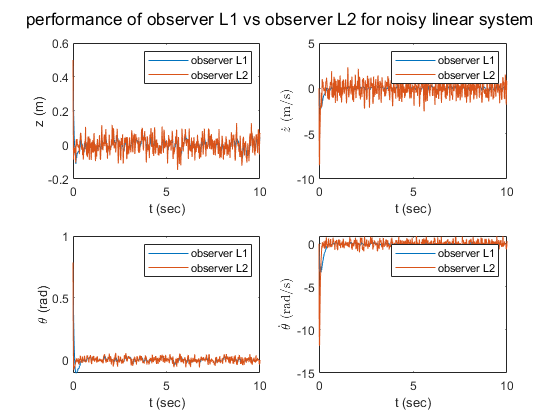

cov_mat = [0.005 0;
            0 0.001];
L_upper = chol(cov_mat);
L_lower = L_upper';
radm_seed = randn(2, 1000);          
radn_vector = L_lower * radm_seed;   % 1000 random column vectors with zero mean and unit variance


W = @(t) interp1(Tspan, radn_vector', t);  % transpose radn_vector to use interp1. Function returns a row vector


linear_noisy_params.A = A_double;
linear_noisy_params.B = B_double;
linear_noisy_params.C= C_double;
linear_noisy_params.K = K;
linear_noisy_params.W = W;


% define parameters for L1 and simulate for nonlinear system
linear_noisy_params.L = L_1;
[t_L1, x_gen_L1]=ode45(@state_estimate_dynamics_linear_noisy,Tspan,x0_gen,options, linear_noisy_params);
z_error_L1 = x_gen_L1(:,5) - x_gen_L1(:,1);
zdot_error_L1 = x_gen_L1(:,6) - x_gen_L1(:,2);
theta_error_L1 = x_gen_L1(:,7) - x_gen_L1(:,3);
thetadot_error_L1 = x_gen_L1(:,8) - x_gen_L1(:,4);


% define parameters for L2 and simulate for nonlinear system
linear_noisy_params.L = L_2;
[t_L2, x_gen_L2]=ode45(@state_estimate_dynamics_linear_noisy,Tspan,x0_gen,options, linear_noisy_params);
z_error_L2 = x_gen_L2(:,5) - x_gen_L2(:,1);
zdot_error_L2 = x_gen_L2(:,6) - x_gen_L2(:,2);
theta_error_L2 = x_gen_L2(:,7) - x_gen_L2(:,3);
thetadot_error_L2 = x_gen_L2(:,8) - x_gen_L2(:,4);

% plotting a figure with 4 subplots for nonlinear system
figure
subplot(2,2,1)              % plotting z
plot(t_L1, z_error_L1(:,1))
hold on                     
plot(t_L2, z_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("z (m)")

subplot(2,2,2)              % plotting z_dot
plot(t_L1, zdot_error_L1(:,1))
hold on                     
plot(t_L2, zdot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{z}$ (m/s)", 'Interpreter','latex')

subplot(2,2,3)              % plotting theta
plot(t_L1, theta_error_L1(:,1))
hold on                     
plot(t_L2, theta_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("\theta (rad)")

subplot(2,2,4)              % plotting theta_dot
plot(t_L1, thetadot_error_L1(:,1))
hold on                     
plot(t_L2, thetadot_error_L2(:,1))
legend('observer L1', 'observer L2')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')

sgtitle('performance of observer L1 vs observer L2 for noisy linear system')


% obtain the MSE of the final 5sec of each component of each simulation
z_L1_errors = z_error_L1(t_L1 > t_L1(end) - 5);
z_L1_MSE = sum(z_L1_errors.^2)/length(z_L1_errors)

z_L1_MSE = 8.3693e-04

z_L2_errors = z_error_L2(t_L2 > t_L2(end) - 5);
z_L2_MSE = sum(z_L2_errors.^2)/length(z_L2_errors)

z_L2_MSE = 0.0021


zdot_L1_errors = zdot_error_L1(t_L1 > t_L1(end) - 5);
zdot_L1_MSE = sum(zdot_L1_errors.^2)/length(zdot_L1_errors)

zdot_L1_MSE = 0.0204

zdot_L2_errors = zdot_error_L2(t_L2 > t_L2(end) - 5);
zdot_L2_MSE = sum(zdot_L2_errors.^2)/length(zdot_L2_errors)

zdot_L2_MSE = 0.6282


theta_L1_errors = theta_error_L1(t_L1 > t_L1(end) - 5);
theta_L1_MSE = sum(theta_L1_errors.^2)/length(theta_L1_errors)

theta_L1_MSE = 1.9626e-04

theta_L2_errors = theta_error_L2(t_L2 > t_L2(end) - 5);
theta_L2_MSE = sum(theta_L2_errors.^2)/length(theta_L2_errors)

theta_L2_MSE = 4.3739e-04


thetadot_L1_errors = thetadot_error_L1(t_L1 > t_L1(end) - 5);
thetadot_L1_MSE = sum(thetadot_L1_errors.^2)/length(thetadot_L1_errors)

thetadot_L1_MSE = 0.0085

thetadot_L2_errors = thetadot_error_L2(t_L2 > t_L2(end) - 5);
thetadot_L2_MSE = sum(thetadot_L2_errors.^2)/length(thetadot_L2_errors)

thetadot_L2_MSE = 0.1363


% Discussion:
% the observation for L1 fluctuates with a smaller magnitude compared to
% the fluction of L2. However, system L2 still decays at a faster rate (as
% seen at the beginning of the simulation period)

% the MSE of L2 is larger than the MSE of L1 for all state components
% because large negative time constants (as achieved through pole
% placements cause the system to react faster to changes in the input
%(observation). Hence, more noise is picked up

% in terms of frequency response,assuming zero input, the transfer function
% becomes (note: Y is input, X is the state -output) is X/Y =  L/(A+LC -s).
% when L2 is designed such that the poles of A+LC is more negative, the
% amplitude of high prequency noise (large s) is amplified more
% drastically. Because noise is random, and high frequency, it has more
% impact in the system with observation matrix = L2